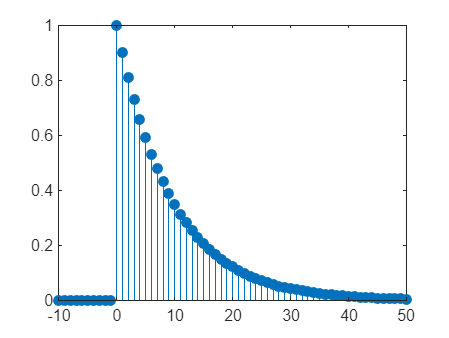

clc;
clear all;

t = -10:50;

for n = 11:61
    u(1,n) = heaviside(n);
    Xn(1,n) = u(1,n) - u(n-10);
    hn(1,n) = (0.9)^(n-11)*u(1,n);
end
stem(t,hn,'filled');
xlim([-10,50]);   
ylim([0,1]);

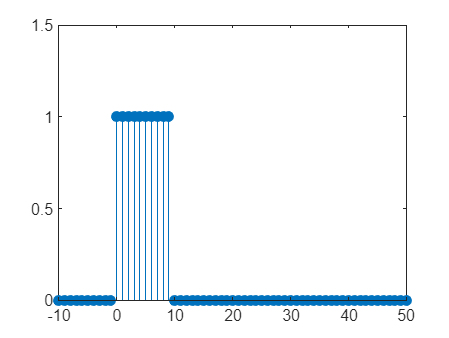

stem(t,Xn,'filled');
xlim([-10,50]);
ylim([0,1.5]);

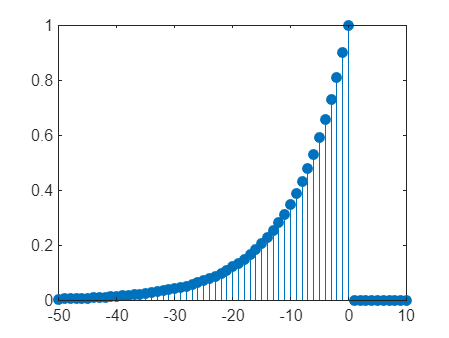

%set h[k] => h[-k]
for n = 11:71
    hn_refelct(1,n-10) = hn(1,72-n);
end
t = -50:10;
stem(t,hn_refelct,'filled');
xlim([-50,10]);

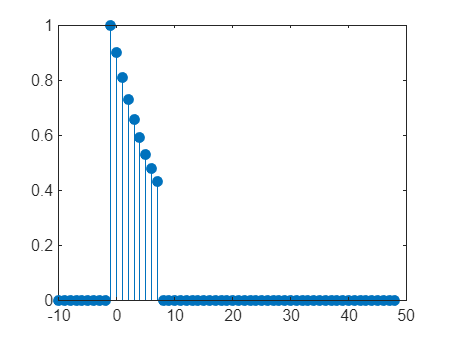

for k = 1:50
    yn(1,k+10) = Xn(k+11)*hn_refelct(-k+52);
end
t = -11:48;   
stem(t,yn,'filled');
xlim([-10,50]);

%set convution
for n = 1:61
    w(1,n) = conv(hn(1,n),Xn(1,n));
end
t = 1:61

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


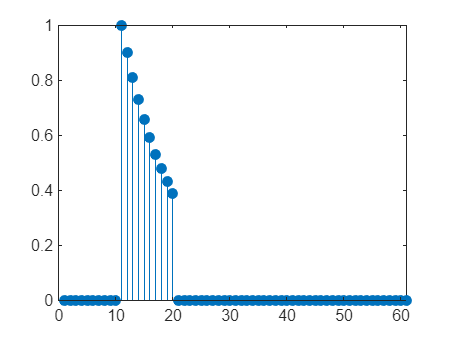

stem(t,w,'filled');